# disadNB-IoT simulation

## transmission

clear
%base message
dataLength=12*2*10;
%messageBits= randi([0 1],dataLength,1)
messageBits=ones(dataLength,1)

messageBits =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


%map bits to qpsk symbols
messageInts=bit2int(messageBits,2)% grouped by 2 bits, converted to dec

messageInts =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


symbolMap=[1+1i, -1+1i, 1-1i, -1-1i] / sqrt(2); %normalized QPSK constellation points
messageSymbols = zeros(size(messageInts, 1), 1);
for k = 1:size(messageInts, 1)
    idx = messageInts(k) + 1; %map index
    messageSymbols(k) = symbolMap(idx); %symbolmap
end

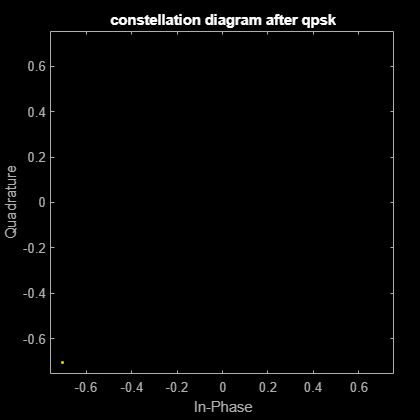

%plot scatterplot
figure;
scatterplot(messageSymbols);
title('constellation diagram after qpsk');

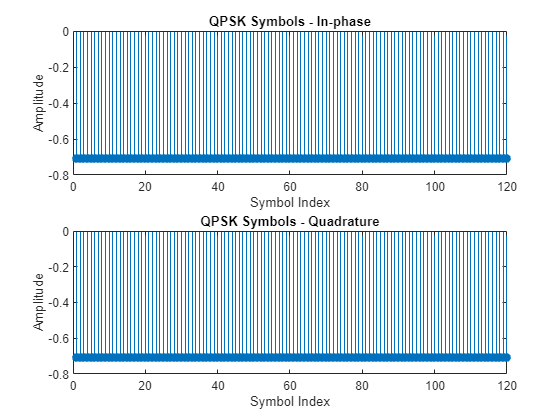

% 
% figure;
% messageSymbols2=pskmod(messageInts,4,pi/4)
% scatterplot(messageSymbols2)
% title('constellation diagram2');

%plot time domain
figure;
subplot(2,1,1);
stem(real(messageSymbols), 'filled');
title('QPSK Symbols - In-phase');
xlabel('Symbol Index');
ylabel('Amplitude');
subplot(2,1,2);
stem(imag(messageSymbols), 'filled');
title('QPSK Symbols - Quadrature');
xlabel('Symbol Index');
ylabel('Amplitude');



% %plot time domain
% figure;
% subplot(2,1,1);
% stem(real(messageSymbols2), 'filled');
% title('QPSK Symbols - In-phase');
% xlabel('Symbol Index');
% ylabel('Amplitude');
% subplot(2,1,2);
% stem(imag(messageSymbols2), 'filled');
% title('QPSK Symbols - Quadrature');
% xlabel('Symbol Index');
% ylabel('Amplitude');


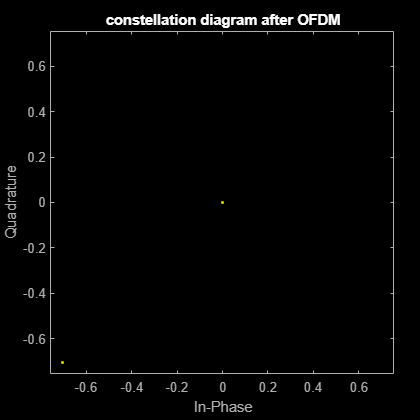

%ofdm
numSC=12;% # subcarriers
cpLen=3;%cyclic prefix length
numSym=7;% # ofdm symbols
bandwidth=180e3;
carrierFreq=890e6;

numSymbolsRequired = numSC * numSym;
if length(messageSymbols) < numSymbolsRequired
    error('Not enough symbols to fill the OFDM frame');
end

ofdmSymbolsMatrix = reshape(messageSymbols(1:numSymbolsRequired), numSC, numSym);%reshape into 12 carrier x7 symbols frame in freq domain

timeDomainSymbols = ifft(ofdmSymbolsMatrix, numSC);%time domain frame, 12 samples

cpSymbols = [timeDomainSymbols(end-cpLen+1:end, :); timeDomainSymbols];

txSignalOFDMA = cpSymbols(:);% (:) reshapes matrix into column



figure
scatterplot(txSignalOFDMA)
title('constellation diagram after OFDM');

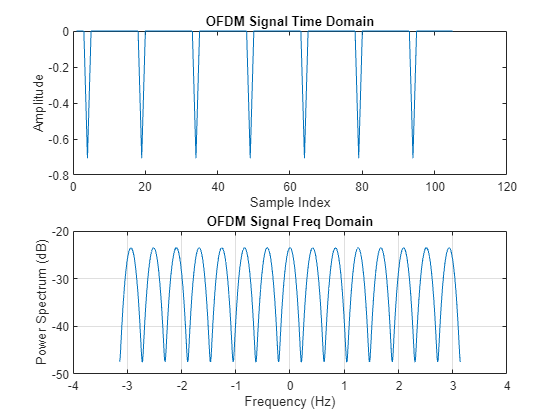


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(txSignalOFDMA));
title('OFDM Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(txSignalOFDMA);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('OFDM Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

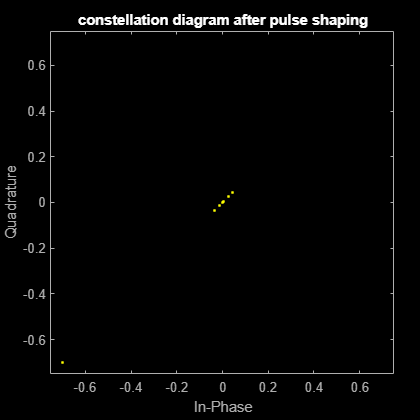

%upsampling
L = 1;  % Upsampling factor
rolloff = 0.25;  % Roll-off factor for the RRC filter
span = 10;  % Filter span in symbols

txSignalUpsampled = upsample(txSignalOFDMA, L);

rrcFilter = rcosdesign(rolloff, span, L);

txSignalShaped = conv(txSignalUpsampled, rrcFilter, 'same');

figure
scatterplot(txSignalShaped)
title('constellation diagram after pulse shaping');

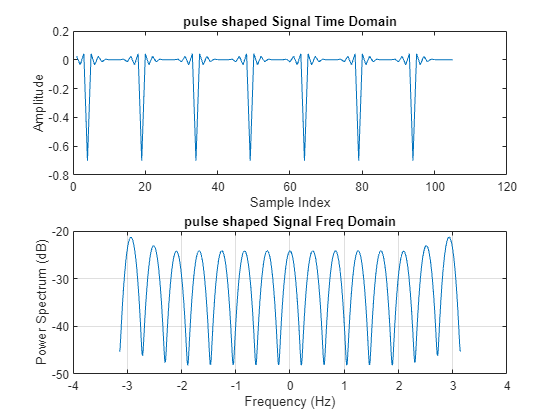


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(txSignalShaped));
title('pulse shaped Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(txSignalShaped);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('pulse shaped Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

% %convert to 900 MHz
% Fc=900e6;
% Fs=2*180e3;
% t = (0:length(txSignalShaped)-1)' / Fs; % Time vector
% cosCarrier = cos(2 * pi * Fc * t);
% sinCarrier = sin(2 * pi * Fc * t);
% txPassband = real(txSignalShaped) .* cosCarrier - imag(txSignalShaped) .* sinCarrier;
% % Plot the time domain signal after upconversion
% figure;
% plot(t(1:length(txPassband)), txPassband); % Plot a segment for better visualization
% title('Passband Signal - Time Domain');
% xlabel('Time (s)');
% ylabel('Amplitude');
% %freq
% [pxx,f] = pspectrum(txSignalShaped,Fs);
% subplot(2,1,2);
% plot(f+Fc,pow2db(pxx))
% grid on
% title('pulse shaped Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')

## channel

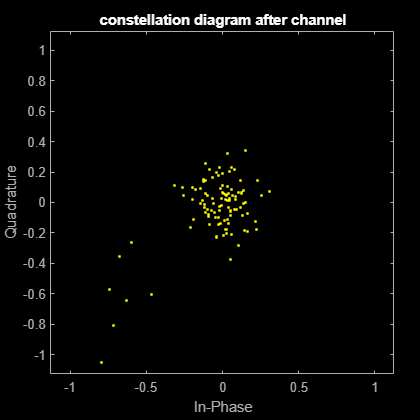

SNR=15;
rxSignal=awgn(txSignalShaped,SNR);
% Plot the time domain signal after channel
figure
scatterplot(rxSignal)
title('constellation diagram after channel');

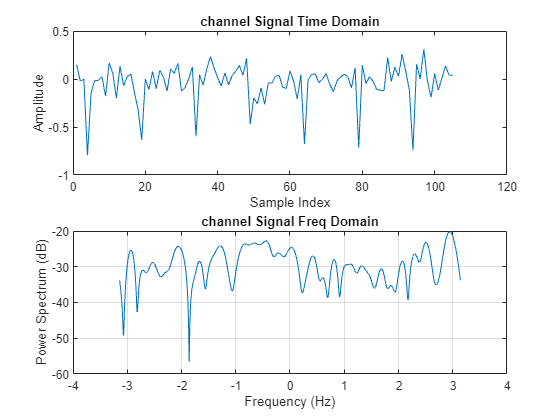


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(rxSignal));
title('channel Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(rxSignal);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('channel Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

## receiver

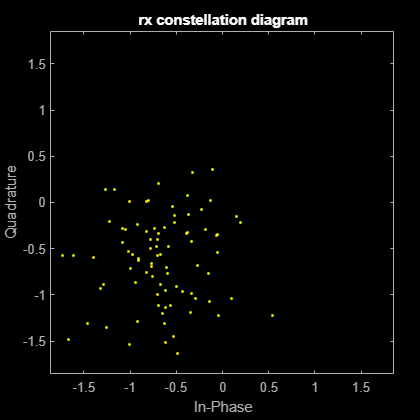

% %downconvert to baseband
% I_component = rxSignal .* cosCarrier;
% Q_component = rxSignal .* sinCarrier;
% 
% filterOrder = 64;
% cutoffFreq = Fc / (2 * Fs); % Normalized cutoff frequency
% lpFilt = designfilt('lowpassfir', 'FilterOrder', filterOrder, 'CutoffFrequency', 0.5);
% 
% I_baseband = filtfilt(lpFilt, I_component);
% Q_baseband = filtfilt(lpFilt, Q_component);
% 
% rxBaseband = I_baseband - 1i * Q_baseband;

%matched filter
matchedFilter = rcosdesign(rolloff, span, L);
rxSignalFiltered = conv(rxSignal, matchedFilter, 'same');

%downsample
rxSignalDownsampled = downsample(rxSignalFiltered, L);

%cp
rxSymbolsWithCP = reshape(rxSignal, numSC + cpLen, numSym);% reattach Cp at the back
rxSymbols = rxSymbolsWithCP(cpLen+1:end, :);%remove cp from front
%fft
rxSymbolsFreq = fft(rxSymbols, numSC);% fft to freq domain
%qpsk
rxQPSKSymbols = rxSymbolsFreq(:);
demodulatedBits = zeros(length(rxQPSKSymbols)*2, 1);
figure;
scatterplot(rxQPSKSymbols);
title('rx constellation diagram');

% Demodulate QPSK symbols to bits
for k = 1:length(rxQPSKSymbols)
    [~, idx] = min(abs(rxQPSKSymbols(k) - symbolMap));
    demodulatedBits(2*k-1:2*k) = de2bi(idx-1, 2, 'left-msb');
end

errors=sum(demodulatedBits'~=messageBits(1:2*7*12)')

errors = 14

nbiot_ber=errors/length(messageBits)

nbiot_ber = 0.0583

samp_rate=15.36e6

samp_rate = 15360000

Rb = (numSC * 2) / ((numSC + cpLen) / samp_rate);
EbN0_sim=SNR*samp_rate/Rb

EbN0_sim = 9.3750

%ber
%https://nl.mathworks.com/help/releases/R2023a/comm/ug/analytical-expressions-used-in-berawgn-function-and-bit-error-rate-analysis-app.html
EbN0=(0:10);
ber=berawgn(EbN0,"psk",4,"nondiff");
figure
semilogy(EbN0',ber,'*')

legend('Theory','Location','Best')
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')
grid on